# Delta Learning rule

## Initialization

clear all;clc;
syms x1 x2 x3
input=[[0.8 0.5 0]; [0.9 0.7 0.3]; [1 0.8 0.5];...
    [0 0.2 0.3]; [0.2 0.1 1.3]; [0.2 0.7 0.8]]

input =     0.8000    0.5000         0
    0.9000    0.7000    0.3000
    1.0000    0.8000    0.5000
         0    0.2000    0.3000
    0.2000    0.1000    1.3000
    0.2000    0.7000    0.8000


## Target of input

y=[1 1 1 -1 -1 -1]'

y =      1
     1
     1
    -1
    -1
    -1


## Initial weights

Initial_weight=zeros(size(input,2),1);

## Learning Rate

eta=0.1;

## Delta Learning Rule

w_Delta=Delta(input,y,Initial_weight,eta)

w_Delta =     7.1916
   -0.5159
   -7.1208


## Plotting Data points and Decision Boundry

figure;
hold on;

% Data Points
scatter3(input(y==1,1),input(y==1,2),input(y==1,3),'+')
scatter3(input(y==-1,1),input(y==-1,2),input(y==-1,3),'r')

% Decision  Boundry
f=(-w_Delta(1)*x1-w_Delta(2)*x2)/w_Delta(3)

$$f = \frac{8097047227786615\,x_{1}}{8017347644110451}-\frac{580833516370344\,x_{2}}{8017347644110451}$$

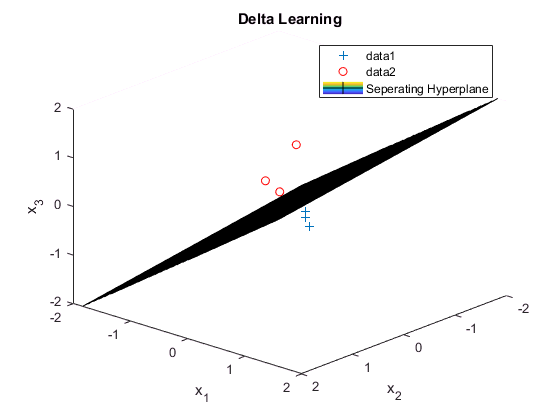

fsurf(f)

title({'Delta Learning'});
xlabel({'x_1'});
zlabel({'x_3'});
ylabel({'x_2'});
legend('data1','data2','Seperating Hyperplane')
view([-42 -28.4]);
axis([-2 2 -2 2 -2 2])
hold off

## Widrow-Hoff Learning Rule

w_widrowHoff=widrowHoff(input,y,Initial_weight,eta)

w_widrowHoff =     2.2334
   -1.0556
   -1.0079


## Plotting Data points and Decision Boundry

figure;
hold on;

% Data Points
scatter3(input(y==1,1),input(y==1,2),input(y==1,3),'+')
scatter3(input(y==-1,1),input(y==-1,2),input(y==-1,3),'r')

% Decision  Boundry
f=(-w_widrowHoff(1)*x1-w_widrowHoff(2)*x2)/w_widrowHoff(3)

$$f = \frac{10058242794074580\,x_{1}}{4539191389035449}-\frac{4754115189338592\,x_{2}}{4539191389035449}$$

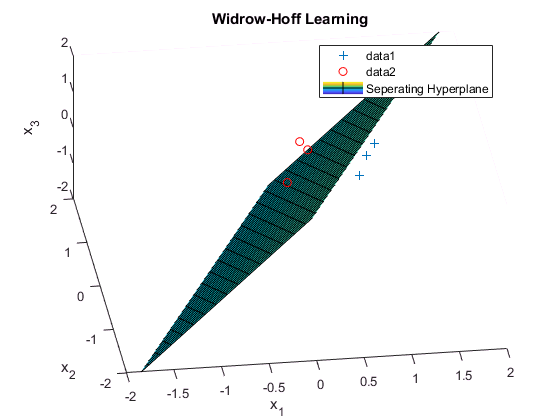

fsurf(f)

title({'Widrow-Hoff Learning'});
xlabel({'x_1'});
zlabel({'x_3'});
ylabel({'x_2'});
legend('data1','data2','Seperating Hyperplane')
view([-7.99999999999995 50.8]);
axis([-2 2 -2 2 -2 2])
hold off